# Threshold VAR

Tutorial file for testing VARs with thresholds

## Housekeeping

clear
close all
clear classes

rehash path

!!! Setting up pathes, please change the first two lines to fit your file structure!!!


bearpath = fullfile("C:","Git","OGR","BEARX-Toolbox","tbx");
tutpath = fullfile("C:","Git","OGR","BEARX-tutorials");


cd(fullfile(bearpath,"bearing"))
activePackage = "threshold";  
import([activePackage + ".*"])  

addpath(fullfile(bearpath,"bear"))


## Convenience functions

The `extremesFunc` function compresses any number of samples (draws from the posterior) into two numbers - the minimum and the maximum.

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

numPresampled = 10000;


## Prepare data and a reduced-form model

The properties specific to the threshold VARs are as follows:

**thresholdVarName  **– The variable serving as the threshold indicator for regime identification

inputTbx = tablex.fromCsv(fullfile(tutpath,"threshold_data.csv"));

estimStart = datex.q(1948,2);
estimEnd = datex.q(2016,4);
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    endogenousNames=["dl_y",	"dl_cpi", "ir_tb", "stock_index"], ...
    thresholdVarName="stock_index", ...
    exogenousNames=[], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=20);

dataH = DataHolder(meta, inputTbx);


### Minnesota dummies

please note that this model is using Minnesota dummies for the priors


minnesotaD = dummies.Minnesota();
minnesotaD

minnesotaD =   Minnesota with properties:

             Lambda: 0.1000
           LagDecay: 1
     Autoregression: 0.8000
          Exogenous: 0
    ExogenousLambda: 100


The estimator/model specific settings are the followings

**VarThreshold** – the prior variance of the threshold

**MaxDelay** – the maxium delay allowed for the threshold variable for regime identification

**ThresholdPropStd** – proposal standard deviation of the MH algorithm of the threshold draws


estimatorR = estimator.Threshold(meta);

modelR = ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR ...
    , dummies={minnesotaD} ...
);


## Estimation/sampling of the reduced form model 


modelR.Estimator.Settings

ans =   Threshold with properties:

              VarThreshold: 10
                  MaxDelay: 4
          ThresholdPropStd: 0.0316
                    Burnin: 0
        StabilityThreshold: Inf
    MaxNumUnstableAttempts: 1000
                 Exogenous: [4×1 logical]
            BlockExogenous: 0
            Autoregression: [4×1 double]
                   Lambda1: 0.1000
                   Lambda2: 0.5000
                   Lambda3: 1
                   Lambda4: [4×1 double]
                   Lambda5: 1.0000e-03


rng(0)
modelR.initialize();
info5 = modelR.presample(numPresampled);


 Presampling from posterior (Threshold) [10000]
 ―――――――――――――――――――――――――――――――――――――――――――――――――◼  100% 





thresholds = zeros(1, numPresampled);
for ii = 1:numPresampled
    thresholds(ii) = modelR.Presampled{ii}.threshold;
end

mean(thresholds)

ans = 0.9306

## Running Unconditional forecast 

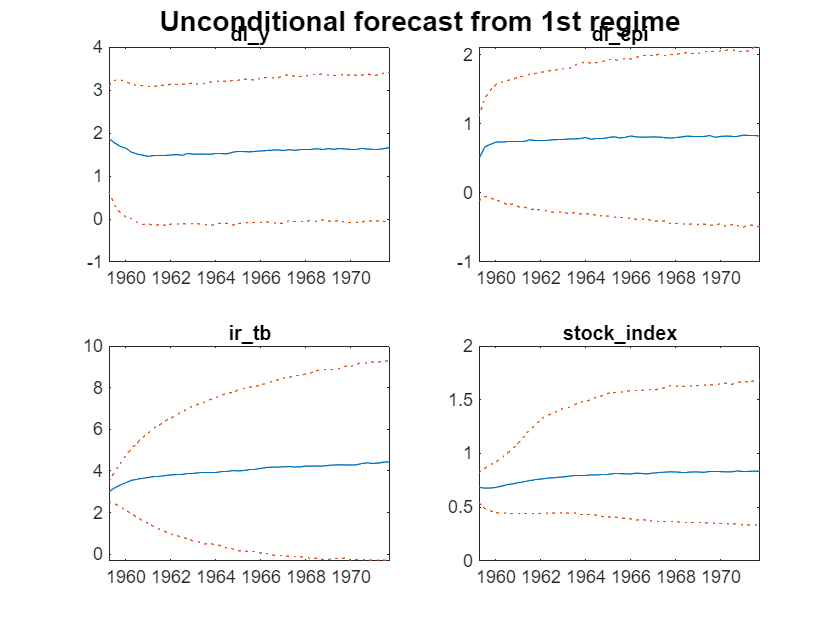

fcastStart1 = datex.shift(modelR.Meta.EstimationEnd, -230);
fcastEnd1 = datex.shift(modelR.Meta.EstimationEnd, -180);
fcastSpan1 = datex.span(fcastStart1, fcastEnd1);

fcastTbx1 = modelR.forecast(fcastSpan1, IncludeInitial=true);
fcastTbx1 = tablex.apply(fcastTbx1, prctileFunc); 
fcastPrctileTbx1 = tablex.flatten(fcastTbx1);

fcastStart2 = datex.shift(modelR.Meta.EstimationEnd, -135);
fcastEnd2 = datex.shift(modelR.Meta.EstimationEnd, -85);
fcastSpan2 = datex.span(fcastStart2, fcastEnd2);

fcastTbx2 = modelR.forecast(fcastSpan2, IncludeInitial=true);
fcastTbx2 = tablex.apply(fcastTbx2, prctileFunc); 
fcastPrctileTbx2 = tablex.flatten(fcastTbx2);

defaultColors = get(0, "defaultAxesColorOrder");

plotSettings = { ...
   {"color"}, {defaultColors(2,:); defaultColors(1,:); defaultColors(2,:)},  ...
   {"lineStyle"}, {":";"-";":"}, ...
};
% 
ch = visual.Chartpack( ...
      span=datex.span(fcastStart1, fcastEnd1), ...
      namesToPlot=[modelR.Meta.EndogenousNames], ...
     plotSettings=plotSettings ...
);

 ch.Captions = "Unconditional forecast from 1st regime";
 ch.plot(fcastPrctileTbx1);

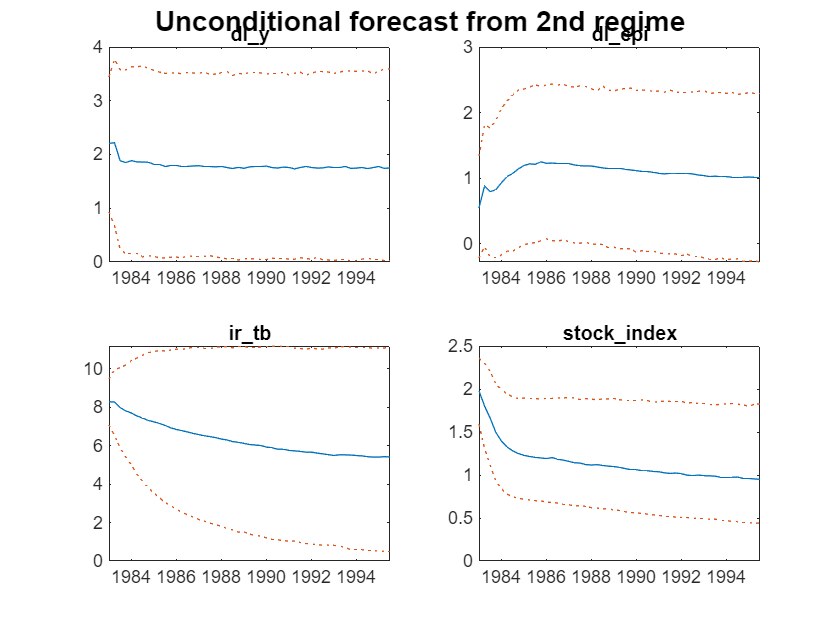


 ch = visual.Chartpack( ...
      span=datex.span(fcastStart2, fcastEnd2), ...
      namesToPlot=[modelR.Meta.EndogenousNames], ...
     plotSettings=plotSettings ...
);

 ch.Captions = "Unconditional forecast from 2nd regime";
 ch.plot(fcastPrctileTbx2);